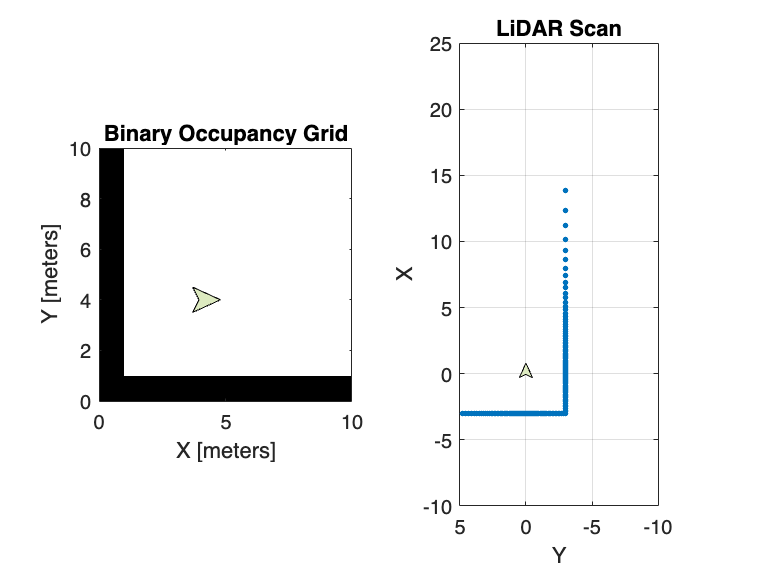

clf;
ax1 = subplot(1, 2, 1);
load('occupancy-warehouse.mat')
show(map)
xlim([0 10])
ylim([0 10])
pose = [4 4 0];
helperPlotRobot(ax1, pose, 0.1);
mapmat = occupancyMatrix(map);
save('occupancy.mat', 'mapmat')
map = binaryOccupancyMap(mapmat);

% Create Lidar Scan
lidar = rangeSensor("Range", [0 15]);
[ranges, angles] = lidar(pose, map);

subplot(1, 2, 2);
scan = lidarScan(ranges, angles);
plot(scan)
xlim([-10 25]);
ylim([-10 5]);
helperPlotRobot(gca, [0 0 0]);

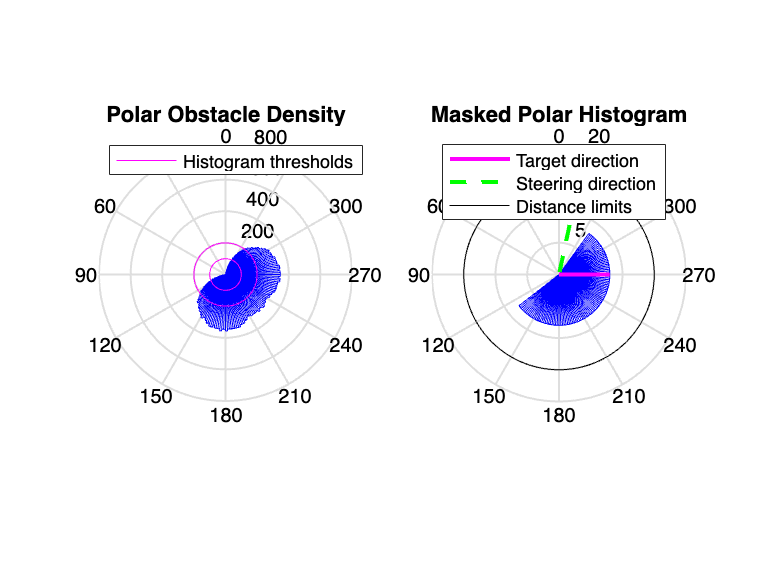

% Run VFH Algorithm
vfh = controllerVFH('UseLidarScan', true);
vfh.SafetyDistance = 1.0;
vfh.DistanceLimits = lidar.Range;
vfh.HistogramThresholds = [100 200];
vfh.MinTurningRadius = 1.0;
vfh.TargetDirectionWeight = 5.0;
steerDir = vfh(scan, -pi / 2);

% subplot doesn't work here
show(vfh)

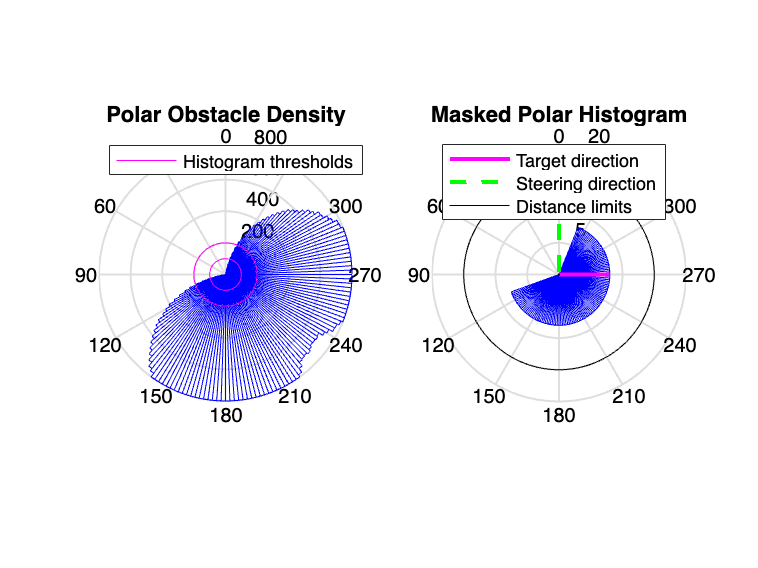

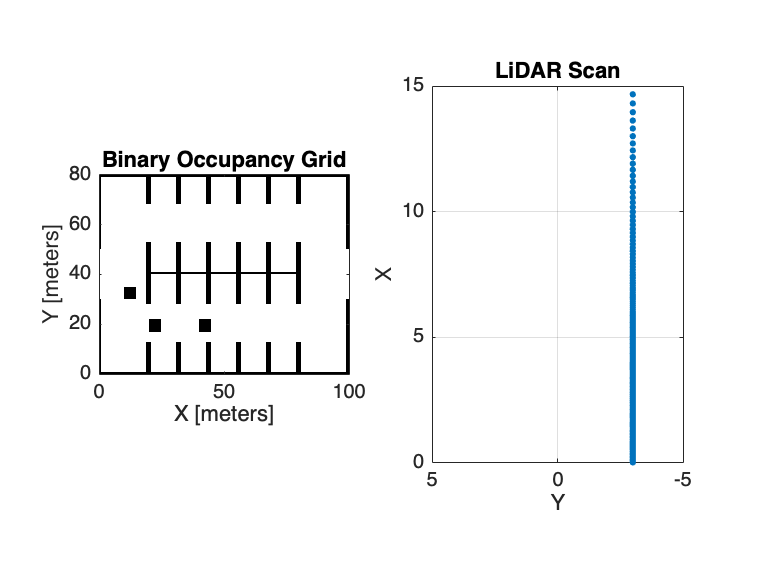

[steerDir, vfh, scan, map] = vfhControllerCoder(pose, -pi / 2, mapmat, 1);

steerDir

steerDir = 0